# EGM and the political equilibrium

The current version is updated in primo February 2022.

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

## 1. Settings

 The main model components are collected in a few structs. To allow for more than one model instance (e.g. with different types of policies), we collect these in one layer here.

out = struct();

To initialize a model, we need to at least specify the relevant parameters that we want, what types of policies are in place (e.g. parameters of $\epsilon,\theta$), and what type of population data we might use. The following simply collects a number of default parameter values, and with the input 'E' uses empirical population data from "Inputdata.xlsx":

out.par = SolveF.setup_US('E'); % with input 'S'.

Add the epsilon/theta values:

out.par.epsilon = 0.5155; out.par.theta = 0.728;

Before we calibrate the model, collect the targets:

target = SolveF.target();

Adjust data:

out.par.xi = 0.3; % labor supply elasticity
target.srate = 0.179; % savings rate
target.pensiontax = 0.124; % pension tax
target.LSI = 1-0.281; % labor share of income
target.h = 0.631; % formal labor supply
target.nu_row = 3; % target year 2020
target.nu_col = 3; % target year 2020
target.nu = out.par.nu(3,3);
target.xi = 0.3;

The *SolveF *includes the following useful functions:

- *identify_policy(par): *Uses the EGM approach outlined in the paper to identify the period-specific policy functions. Returns a struct with fields *self.h, self.tau, self.tau_m. *This assums that the system is contributive $(\epsilon>0)$. 

- *sim_u(par): *Returns a path for labor supply, PEE taxes, and savings rates (*self.h, self.tau, self.srate *respectively) when pension type is universal $(\epsilon=0$).   

- *sim_c_unique(par): *returns a path for labor supply and PEE taxes (*self.h, self.tau, self.srate *respectively) when pension type is contributve $(\epsilon>0)$. 

- *cal_ss_c(par,target): *Calibrates the model using a steady state approximation; the steady state is approximated using a finite horizon EGM version with constant $\nu_t$. Assumes that $\epsilon>0$.

- *cal_dyn_c(par,target): *Dynamic calibration with the finite horizon EGM. Assumes that $\epsilon>0$

## 2. Baseline calibration and simulation

Our default approach is to use dynamic calibration, assuming the pension system is contributive (and expected to stay this way). This overwrites the existing parameter values with calibrated ones:

out.par = SolveF.cal_dyn_c_US(out.par,target);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Given the calibrated parameter values, we simulate time path by defining the policy and simulating from it:

[out.sol, out.par] = SolveF.identify_policy(out.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

out.sim = SolveF.sim_c_unique(out.par,out.sol);

## 3. Covid shock to labor preferences

We assume that covid - amongst other things - represents a shock to labor productivity/preferences. 

- To perform this shock, we say that for all $t\leq2020$, all parameters are expected to be constant. Thus, we start by solving for an entire path from 1950-2100 calibrated to targets for 2020. 

- Take the path for $t<2020$ as given for all relevant variables. Now, identify the change in $X$ that warrants a decrease in the formal labor supply from $0.634$ to $0.623$. This is a simplification of the full calibration procedure. 

Create new par struct that only contain data for years after 2020:

par = out.par;
par.Ndata = 1; % only use the relevant data series that enters 2020
par.years = par.years(3:end,3); % only use time series for 2020-...
par.nu = par.nu(3:end,3); % 
par.T = length(par.nu);
par.dates = par.years';
par.nu_v = par.nu;
par.T_v = par.T;

Solve for the parameter X that results in the wanted level of labor supply:

target.h = 0.622;
target.nu_col = 1;
target.nu_row = 1;
h0 = out.sim.h(find(out.par.dates'==2020)-1);
par = SolveF.laborShock(par,target,h0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Given the new parameters, find solution and simulate path:

parSimulate = out.par;
parSimulate.X = par.X;
[sol, parSimulate] = SolveF.identify_policy(parSimulate);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

sim = SolveF.sim_c_unique(parSimulate,sol);

Simulate the effect of the new PEE taxes, but with the old parameter value of $X$: 

sim.tau(out.par.dates'<2020) = out.sim.tau(out.par.dates'<2020);
sim_CounterFactual = SolveF.sim_c_GivenTaxes(out.par,sim.tau);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## 4. Reporting/plotting results

### 4.1. Plots

Define the main settings (colormaps, font sizes etc.):

psettings = figs.def_psettings(struct());
print = 1; % If 1 print to pdf, if 0 don't.
prefix = 'US'; % Add a prefix to all pdfs.
sim.h(out.par.dates'<2020) = nan;
sim.tau(out.par.dates'<2020) = nan;
sim.srate(out.par.dates'<2020) = nan;
sim_CounterFactual.h(out.par.dates'<2020) = out.sim.h(out.par.dates'<2020);

Print worker-to-retiree ratio:

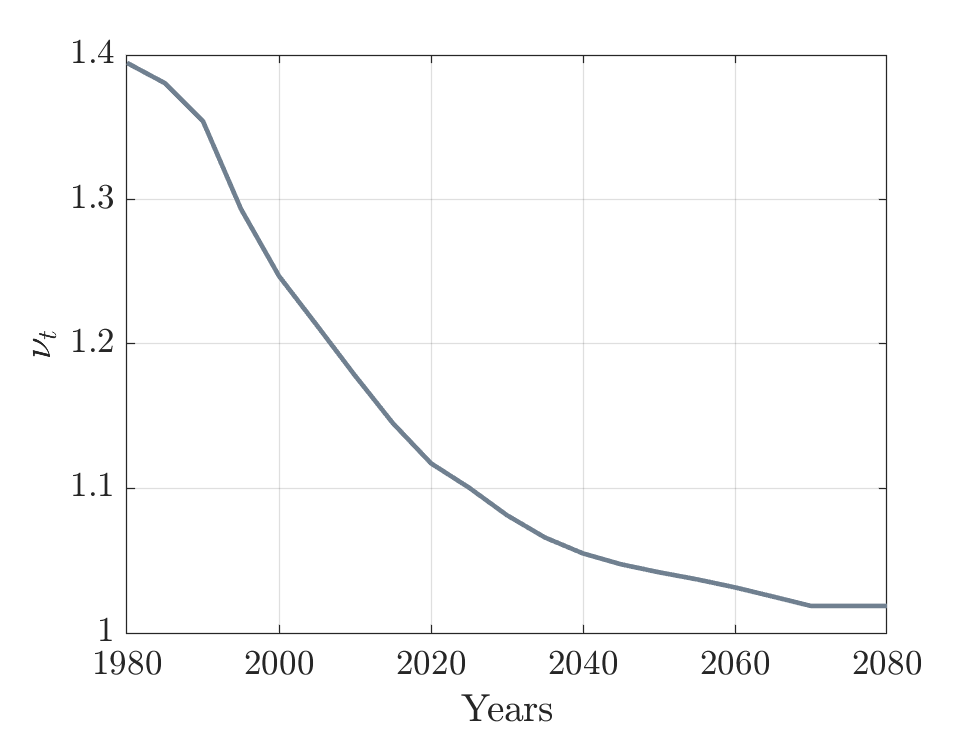

figs.w2r_ratio(out.par.dates,out.par,psettings,print,prefix);

Print tax policy before/after covid shock:

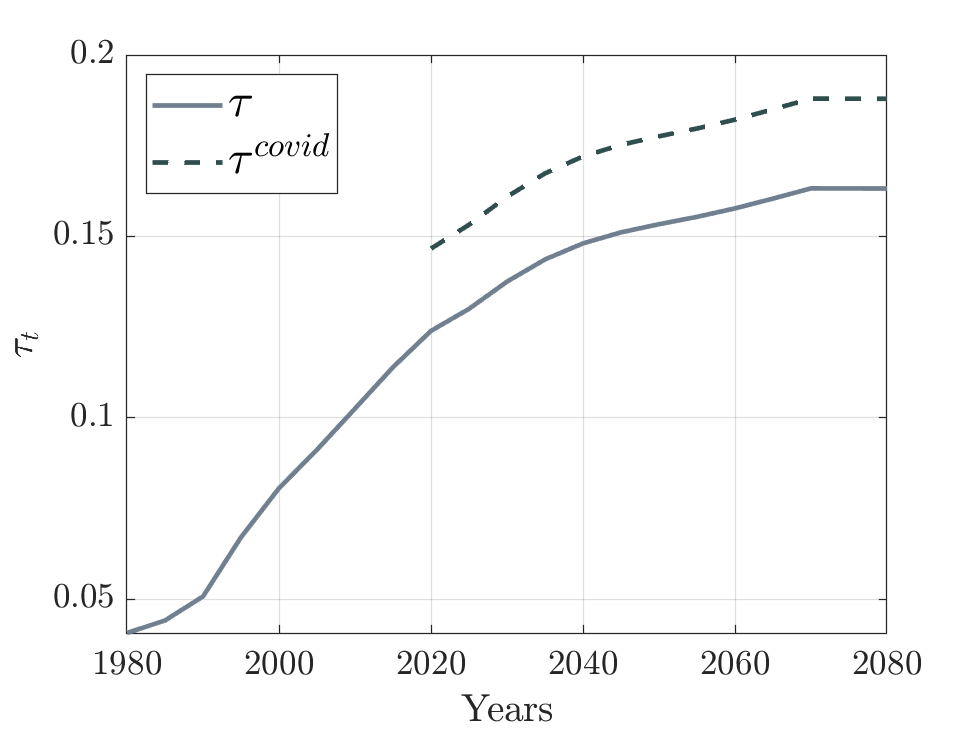

figs.comparetaxes_US(out.par.dates,psettings,out.sim,sim,print,prefix);

Print savings rate:

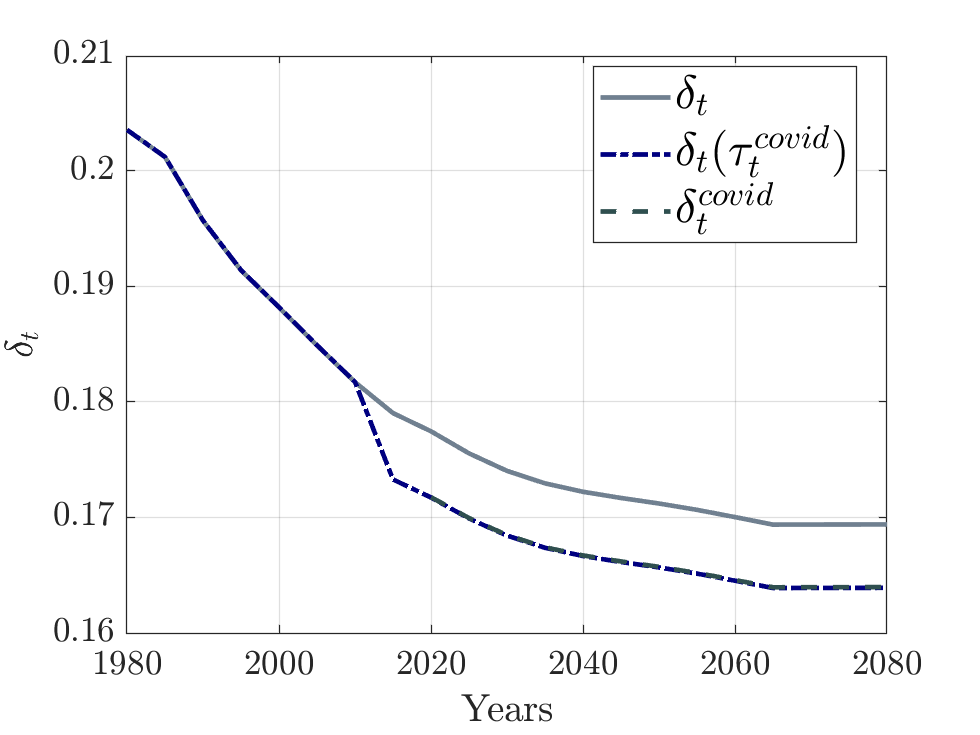

figs.comparesavings_US(out.par.dates,psettings,out.sim,sim,sim_CounterFactual,print,prefix);

Print labor supply:

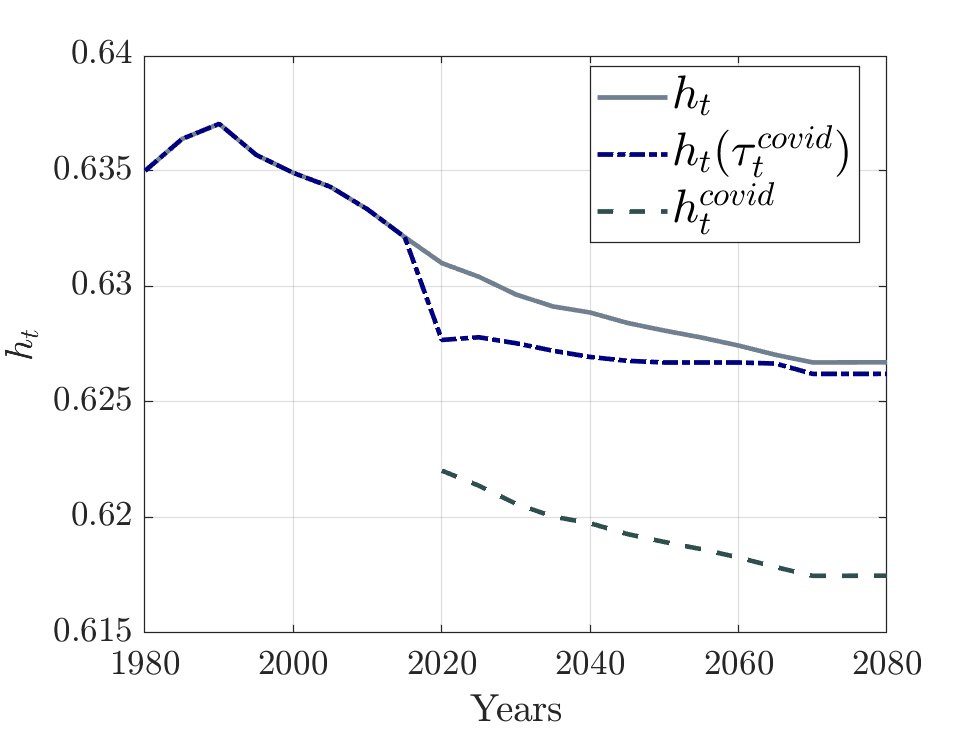

figs.comparelabor_US(out.par.dates,psettings,out.sim,sim,sim_CounterFactual,print,prefix);

### 4.2.  Tables

Pick out year 2020 and inspect:

table = struct(); obs = 15;
table.tau = NaN(2,1);
table.tau(1) = out.sim.tau(obs);
table.tau(2) = sim.tau(obs);
table.h = NaN(2,1);
table.h(1) = out.sim.h(obs);
table.h(2) = sim.h(obs);
table.srate = NaN(2,1);
table.srate(1) = out.sim.srate(obs-1);
table.srate(2) = sim.srate(obs);